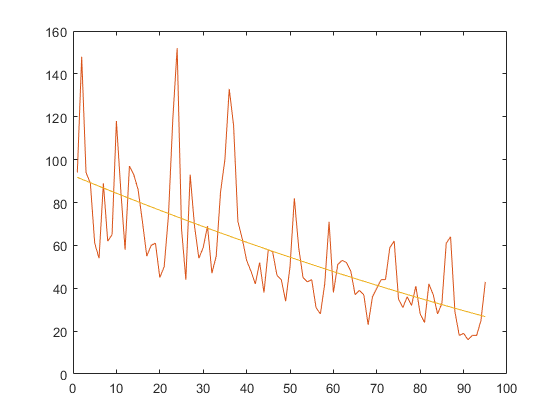

clc;
clear;
close all;
[file,path] = uigetfile({'*.xlsx';'*.xls'},'File Selector');
filepath=strcat(path,file);
XJData = xlsread(filepath);


X1 =XJData(:,3);
plot(X1)
hold on;

X1 =XJData(:,3);
Xp1 = X1;

numsize = size (X1);
numsize = numsize(1);

plot(X1)
hold('on');

timelong = 1:numsize;
timelong =timelong';
p = polyfit(timelong,X1,2);
plot(polyval(p,timelong))
hold on;

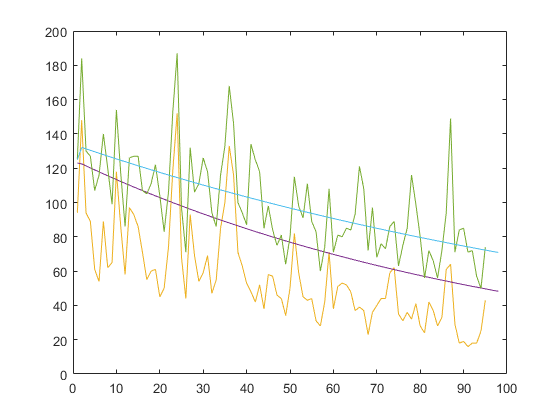

            
X2 =XJData(:,4);
plot(X1)
hold on;

[X2,c2,error12,error22]=GM11(X2,3);
plot(X2)
hold on;

X3 =XJData(:,5);
plot(X3)
hold on;

[X3,c3,error13,error23]=GM11(X3,3);
plot(X3)
hold on;


Xs = [X1' X2' X3'];

错误使用 horzcat
要串联的数组的维度不一致。


Xs = flipud(Xs);

legend('原PM2.5','预测PM2.5趋势','原PM10','预测PM10趋势','原AQI','预测AQI趋势')
title('灰色预测')
xlabel('月份')
ylabel('质量')


function [X,c1,error1,error2]=GM11(X0,k)
% 其中X0为输入序列，k为预测长度，
% X为预测输出序列，c为后验差检验数，error1为残差，error2为相对误差
format long;
n=length(X0);
X1=[];
X1(1)=X0(1);
for i=2:n
X1(i)=X1(i-1)+X0(i);               %计算累加生成序列
end
for i=1:n-1
B(i,1)=-0.5*(X1(i)+X1(i+1));   %计算B，Yn
B(i,2)=1;
Y(i)=X0(i+1);
end
alpha=(B'*B)^(-1)*B'*Y';            %做最小二乘估计
a=alpha(1,1);
b=alpha(2,1);
d=b/a;                            %计算时间响应函数参数
c=X1(1)-d;
X2(1)=X0(1);
X(1)=X0(1);

for i=1:n-1
X2(i+1)=c*exp(-a*i)+d;
 X(i+1)=X2(i+1)-X2(i);    
 %计算预测序列
end
for i=(n+1):(n+k)
    X2(i)=c*exp(-a*(i-1))+d;         %计算预测序列
    X(i)=X2(i)-X2(i-1);
end
for i=1:n
    error(i)=X(i)-X0(i);
    error1(i)=abs(error(i));       %计算残差
    error2(i)=error1(i)/X0(i);     %计算相对误差
    c1=std(error1)/std(X0);             %计算后验差检验数
end
  c1=std(error1)/std(X0);             %计算后验差检验数
end